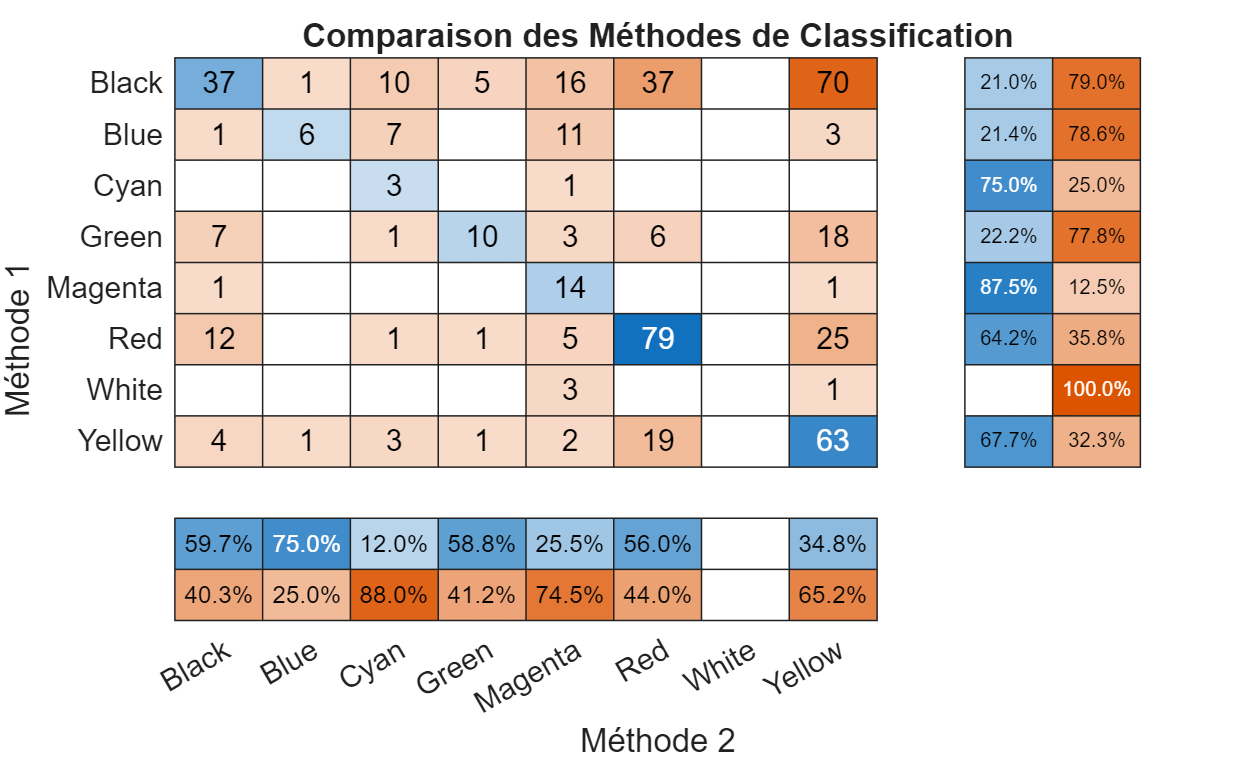

% --- 1. Données d'exemple (Remplace par tes vecteurs réels) ---
% 8 classes : 1=Red, 2=Green, 3=Blue, 4=Yellow, 5=Magenta, 6=Cyan, 7=White, 8=Black
% Imaginons 100 neurones
load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcell_registration.mat");
method2 = colorcell;
% load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcelldist3.mat");%colorcell new Aurélie
load("E:\Data\Aurelie\data\nocues\444119\220919_plane0\colorcellnew.mat"); % old colorcell original 
method1 = uint8(colorcell);
n_neurons = size(method1,1);
% --- 2. Définition des labels ---
labels_str = {'Red', 'Green', 'Blue', 'Yellow', 'Magenta', 'Cyan', 'White', 'Black'};
n_classes = length(labels_str);
all_classes = 1:8; 

% --- 3. Calcul de la Matrice de Confusion ---
% C(i,j) = nombre de neurones classés 'i' par méthode 1 et 'j' par méthode 2
C = confusionmat(method1, method2,'Order', all_classes);

% --- 4. Visualisation ---
figure;
% On utilise 'confusionchart' (dispo depuis R2018b) qui est très esthétique
cm = confusionchart(C, labels_str);

% Personnalisation du graphique
cm.Title = 'Comparaison des Méthodes de Classification';
cm.XLabel = 'Méthode 2';
cm.YLabel = 'Méthode 1';
cm.RowSummary = 'row-normalized'; % Affiche les % par ligne à droite
cm.ColumnSummary = 'column-normalized'; % Affiche les % par colonne en bas


% --- 5. Calcul du Taux d'Accord Global (Accuracy) ---
accuracy = trace(C) / sum(C(:)) * 100;
fprintf('Accord global entre les deux méthodes : %.2f%%\n', accuracy);

Accord global entre les deux méthodes : 43.35%



idx_black = 8; 

% On crée un masque de tout ce qui n'est PAS Black
% On veut exclure la ligne Black et la colonne Black
C_no_black = C;
C_no_black(idx_black, :) = []; % Supprime la ligne Black
C_no_black(:, idx_black) = []; % Supprime la colonne Black (attention aux indices décalés !)
% MIEUX : Utiliser les indices pour extraire la sous-matrice
idxs_to_keep = setdiff(1:8, idx_black);
C_active = C(idxs_to_keep, idxs_to_keep);

% Calcul de la nouvelle accuracy
accuracy_active = trace(C_active) / sum(C_active(:)) * 100;

fprintf('Accuracy sur les neurones actifs (sans Black) : %.2f%%\n', accuracy_active);

Accuracy sur les neurones actifs (sans Black) : 60.76%



% % --- 6. (Optionnel) Version "Heatmap" manuelle ---
% % Si tu as une vieille version de MATLAB sans confusionchart :
% figure;
% imagesc(C);
% colormap(parula);
% colorbar;
% xlabel('Méthode 2'); ylabel('Méthode 1');
% set(gca, 'XTick', 1:8, 'XTickLabel', labels_str);
% set(gca, 'YTick', 1:8, 'YTickLabel', labels_str);
% title(['Matrice de Confusion (Accord: ' num2str(accuracy, '%.1f') '%)']);
% % Ajout des nombres dans les cases
% for i = 1:8
%     for j = 1:8
%         text(j, i, num2str(C(i,j)), 'HorizontalAlignment', 'center', 'Color', 'w', 'FontWeight', 'bold');
%     end
% end
